clc; close all;

## Model Parameters

noLoadCurrent = 2.1; % Amp
noLoadSpeed = 5600; % RPM
noLoadSpeed_rad = noLoadSpeed * 2*pi / 60; % rad/s
Km = 0.04025; % Nm / Amp

R = 0.3; % 0.19; % Ohms
L = 188e-6; % Henrys

J_X = 550 / 1000 / 100^2; %kg*m^2
J_Y = 1750 / 1000 / 100^2; %kg*m^2
J_theta = 612 / 1000 / 100^2; %kg*m^2

Jm = 3.5^2/4.*[J_X+J_Y J_X-J_Y; J_X-J_Y J_X+J_Y] + J_theta*eye(2);
J_inv = inv(Jm);

B_X = 18*noLoadCurrent * Km / noLoadSpeed_rad; % Nms
B_Y = 6*noLoadCurrent * Km / noLoadSpeed_rad; % Nms

Bm = [B_X 0; 0 B_Y];

Create state space model from parameters

A = zeros(6);
A(1:2,:) = [0 0 1 0 0 0; 0 0 0 1 0 0;];
A(3:4,:) = [zeros(2), -J_inv*Bm, J_inv*Km];
A(5:6,:) = [zeros(2), -Km/L * eye(2), -R/L * eye(2)];
B = [zeros(4,2); eye(2)*1/L];
C = [eye(2) zeros(2,4)];
D = zeros(2);

Position to Angle Transforms and unit conversions

theta_rad_to_xy_cm = [1,1;1,-1]*3.5/2;
xy_cm_to_theta_rad = inv(theta_rad_to_xy_cm);
rad_sec_to_rpm = 60/(2*pi);

## Controller Parameters

PID controller

% k_p = 1.0; % 15;
% k_i = 0; %10;
% k_d = 0.0003; %.5;

Feed forward gains from inverse of transfer function

Kff = minreal(inv(tf(ss(A,B,C,D)))).numerator;

Kff{1,1} = Kff{1,1};
Kff{1,2} = Kff{1,2};
Kff{2,1} = Kff{2,1};
Kff{2,2} = Kff{2,2};

format shortEng
Kff

Kff = 2×2 cell array
    {[    3.5759e-006 5.7183e-003 59.5873e-003 -60.4043e-018]}    {[-1.7165e-006 -2.7391e-003 -59.8682e-018 0.0000e+000]}
    {[-1.7165e-006 -2.7391e-003 -45.0115e-018 -184.8923e-033]}    {[   3.5759e-006 5.7102e-003 46.6958e-003 5.4162e-018]}


fmt = '%d,';
str11 = num2str(Kff{1,1}, fmt)

str11 = '3.575853e-06, 5.718267e-03, 5.958733e-02,-6.040430e-17,'

str12 = num2str(Kff{1,2}, fmt)

str12 = '-1.716522e-06,-2.739130e-03,-5.986824e-17,            0,'

str21 = num2str(Kff{2,1}, fmt)

str21 = '-1.716522e-06,-2.739130e-03,-4.501154e-17,-1.848923e-31,'

str22 = num2str(Kff{2,2}, fmt)

str22 = '3.575853e-06,5.710188e-03,4.669578e-02,5.416168e-18,'

disp(strcat('{ { {',str11,'},{',str12,'} }, { {',str21, '},{', str22,'} } }'))

{ { {3.575853e-06, 5.718267e-03, 5.958733e-02,-6.040430e-17,},{-1.716522e-06,-2.739130e-03,-5.986824e-17,            0,} }, { {-1.716522e-06,-2.739130e-03,-4.501154e-17,-1.848923e-31,},{3.575853e-06,5.710188e-03,4.669578e-02,5.416168e-18,} } }


## Get experimental data from CSV file

csv_signature = "BEGIN CSV";

folder_name = "../BluePill-LLC/H-bot pwm test data/X";
% folder_name = "../BluePill-LLC/data/";
all_files = dir(folder_name);

### Change this line to select a file

most_recent_file = all_files(end-2).name

most_recent_file = '20230323_time1538_pwm50.csv'

file_name = fullfile(folder_name, most_recent_file);
file_contents = fileread(file_name);

content_begin = regexp(file_contents, csv_signature);
content_end = regexp(file_contents, '\n.*$', 'end');

if isempty(content_begin)
    error("Did not find CSV signature in file")
end

data = file_contents(content_begin+11:content_end);

FID = fopen('temp.csv', 'w');
fprintf(FID, data);
fclose(FID);

data = readtable('temp.csv', 'Delimiter', ',');

## Compute values required for analysis

data.delta_t_ms_ = [NaN; diff(data.Time_ms_)];

Left and right motor target positions

lr = rowfun(@(x,y) 180/pi*(xy_cm_to_theta_rad*[x;y])', data(:,{'X_Target_cm_','Y_Target_cm_'}));
lr = table2array(lr);
data = addvars(data, lr(:,1), lr(:,2), 'NewVariableNames', {'Left_Target_deg_','Right_Target_deg_'});

Left and right motor actual positions

data.Left_Actual_deg_ = data.Left_Target_deg_ - data.Left_Error_deg_;
data.Right_Actual_deg_ = data.Right_Target_deg_ - data.Right_Error_deg_;

Compute Left_Velocity and Right_Velocity

data.Left_Velocity_deg_s_ = [NaN; diff(data.Left_Actual_deg_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Right_Velocity_deg_s_ = [NaN; diff(data.Right_Actual_deg_) ./ data.delta_t_ms_(2:end) .* 1000];

Compute X and Y actual positions motor angles

xy = rowfun(@(x,y) pi/180*(theta_rad_to_xy_cm*[x;y])', data(:,{'Left_Actual_deg_','Right_Actual_deg_'}));
xy = table2array(xy);
data = addvars(data, xy(:,1), xy(:,2), 'NewVariableNames', {'X_Actual_cm_','Y_Actual_cm_'});

Compute X velocity and Y velocity

data.X_Velocity_cm_s_ = [NaN; diff(data.X_Actual_cm_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Y_Velocity_cm_s_ = [NaN; diff(data.Y_Actual_cm_) ./ data.delta_t_ms_(2:end) .* 1000];

data.X_Accel_cm_s2_ = [NaN; diff(data.X_Velocity_cm_s_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Y_Accel_cm_s2_ = [NaN; diff(data.Y_Velocity_cm_s_) ./ data.delta_t_ms_(2:end) .* 1000];

% figure;
% hold on
% plot(data.Time_ms_ / 1000, movmean(data.X_Accel_cm_s2_, 10));
% plot(data.Time_ms_ / 1000, movmean(data.Y_Accel_cm_s2_, 10));

Compute X target velocity and Y target velocity 

data.X_Target_Velocity_cm_s_ = [NaN; diff(data.X_Target_cm_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Y_Target_Velocity_cm_s_ = [NaN; diff(data.Y_Target_cm_) ./ data.delta_t_ms_(2:end) .* 1000];

## Compare simulation results to experimental results

clf
f = figure('pos',[0,0,800,700]);
subplot(2,1,1);
% set(gcf,'visible','on','position',[850 0 800 600]);
hold on

plot(data.Time_ms_ / 1000, data.Left_PWM, '-k','LineWidth',2)
ylim([-60 60])
title('Input')
ylabel('PWM (-100 to 100)')

subplot(2,1,2);
hold on
plot(data.Time_ms_ / 1000, data.X_Velocity_cm_s_, 'ro','linest','none');
plot(data.Time_ms_ / 1000, -data.Y_Velocity_cm_s_, 'o','linest','none','color',[0 0.3 1]);

Run simulation and plot the output on top of the experimental data

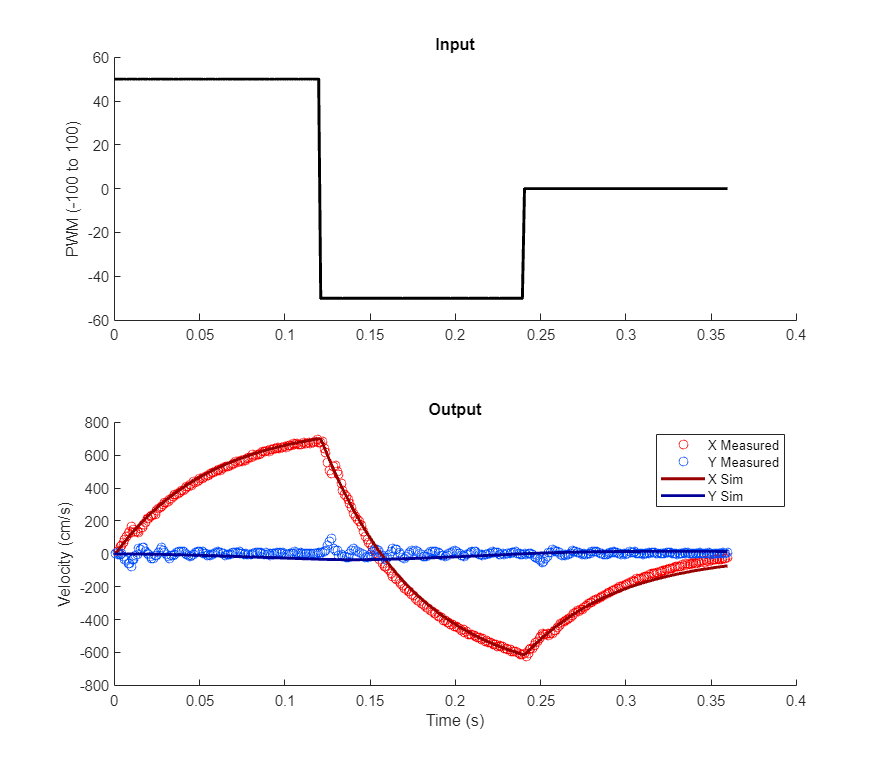

out = sim('H_bot_model_PWM','SaveOutput','on','OutputSaveName','yout','SaveFormat','Dataset');
plot(out.simout.Time,out.simout.Data(:,1),'linewidth',2,'color',[0.6 0 0]);
plot(out.simout.Time,out.simout.Data(:,2),'linewidth',2,'color',[0 0 0.6]);

title('Output');
legend({'X Measured', 'Y Measured', 'X Sim', 'Y Sim'});
xlabel("Time (s)");
ylabel("Velocity (cm/s)");
xlim([0,0.4])
ylim([-800 800])
exportgraphics(f,'pwmplot.png','Resolution',600)

Resample simulation data at the timestamps present in the experiment data

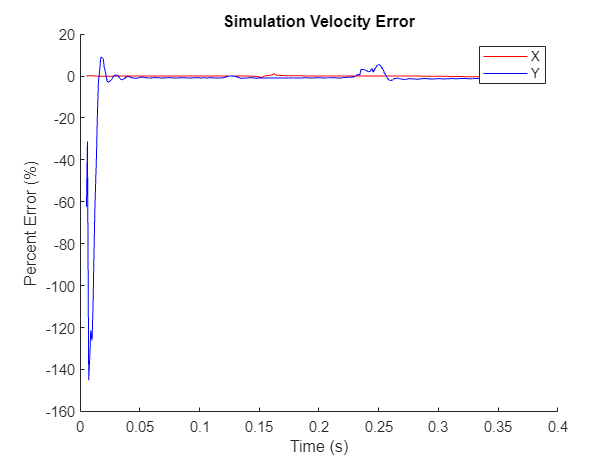

resampledSim = resample(timeseries(out.simout), data.Time_ms_/1000);

rel_error_x = movmean((data.X_Velocity_cm_s_ - resampledSim.Data(:,1))./resampledSim.Data(:,1), 10);
rel_error_y = movmean((data.Y_Velocity_cm_s_ - resampledSim.Data(:,2))./resampledSim.Data(:,2), 10);

figure
hold on
% set(gcf, "visible", "on", 'position', [100 100 600 400])

plot(resampledSim.Time, rel_error_x, '-r')
plot(resampledSim.Time, rel_error_y, '-b')

legend({'X', 'Y'})
title('Simulation Velocity Error')
xlabel('Time (s)')
ylabel('Percent Error (%)')